# Proyecto Final de Algoritmos Numéricos por Computadora

## Modelado del descubrimiento de Neptuno debido a sus efectos sobre la órbita de Urano

Realizado por: 

- Silvestre Leonardo González Abreu        170404

- Andrea de Anda Kuri                                173347

## Planteamiento

    Urano fue descubierto por Sir [William Herschel](https://es.wikipedia.org/wiki/William_Herschel) en 1781, fue el primer planeta en ser descubierto a través de un telescopio. Aún no completaba una vuelta alrededor del Sol cuando en la década de 1840 se notaron anomalías en su órbita que no podían ser explicadas por la teoría de la gravedad de Newton. Poco después [John Couch Adams](https://en.wikipedia.org/wiki/John_Couch_Adams) (1819-1892) y [Urbain Le Verrier](https://en.wikipedia.org/wiki/Urbain_Le_Verrier) (1811-1877) propusieron la existencia de un octavo planeta en 1845 y 1846 respectivamente. Basándose en las perturbaciones observadas en la órbita de Urano y en la ley de la gravitación universal fueron capaces de predecir su órbita y su posición, lo que llevó a su observación y definitivo descubrimiento en la noche del 23 de septiembre de 1846. La primera observación la realizó, en su primer intento, [Johann Galle](https://en.wikipedia.org/wiki/Johann_Gottfried_Galle) (1812-1910). Como consecuencia [François Arago](https://es.wikipedia.org/wiki/Fran%C3%A7ois_Arago) (1786-1853) se refirió a Le Verrier como "el hombre que descubrió un planeta con un lápiz".

## Modelado físico

El movimiento de los planetas en el sistema solar puede ser decrito, como se mencionó, por la teoría de la gravedad de Newton. Para el caso de dos cuerpos se tiene:


$$F=G\frac{m\;m^{\prime } }{r^3 }\mathit{\mathbf{r}}$$



$$\begin{array}{l}
\Rightarrow F=G\frac{m\;m^{\prime } }{r^3 }\left({\mathit{\mathbf{r}}}^{\prime } -\mathit{\mathbf{r}}\right)\;\;,{\;F}^{\prime } =G\frac{m\;m^{\prime } }{r^3 }\left(\mathit{\mathbf{r}}-{\mathit{\mathbf{r}}}^{\prime } \right)\\
\textrm{donde}\;m\;\textrm{es}\;\textrm{la}\;\textrm{masa},r\;\textrm{el}\;\textrm{vector}\;\textrm{de}\;\textrm{posición}\;y\;G\;\textrm{la}\;\textrm{constante}\;\textrm{de}\;\textrm{gravitación}\;\textrm{universal}\ldotp 
\end{array}$$


Como condiciones iniciales se utilizaron las posiciones y velocidades de los planetas el 6 de abril de 2018.

global G m;

G = 6.67428E-11;    %constante gravitacional

mSol=1.98854E+30;   %masa del Sol
mMerc=3.30200E+23;  %masa de Mercurio
mVenu=4.86850E+24;  %masa de Venus
mEart=5.97219E+24;  %masa de Tierra
mMars=6.41850E+23;  %masa de Marte
mJupi=1.89813E+27;  %masa de Jupiter
mSatu=5.68319E+26;  %masa de Saturno
mUran=8.68103E+25;  %masa de Urano
mNept=1.02410E+26;  %masa de Neptuno
mPlut=1.30700E+22;  %masa de Plutón

m=[mSol;mMerc;mVenu;mEart;mMars;mJupi;mSatu;mUran;mNept;mPlut];   %vector de masas

r0Sol=[1.81899E+08;9.83630E+08;-1.58778E+07];   %posicion inicial del Sol
r0Merc=[-5.67576E+10;-2.73592E+10;2.89173E+09]; %posicion inicial de Mercurio
r0Venu=[4.28480E+10;1.00073E+11;-1.11872E+09];  %posicion inicial de Venus
r0Eart=[-1.43778E+11;-4.00067E+10;-1.38875E+07];    %posicion inicial de Tierra
r0Mars=[-1.14746E+11;-1.96294E+11;-1.32908E+09];    %posicion inicial de Marte
r0Jupi=[-5.66899E+11;-5.77495E+11;1.50755E+10]; %posicion inicial de Jupiter
r0Satu=[8.20513E+10;-1.50241E+12;2.28565E+10];  %posicion inicial de Saturno
r0Uran=[2.62506E+12;1.40273E+12;-2.87982E+10];  %posicion inicial de Urano
r0Nept=[4.30300E+12;-1.24223E+12;-7.35857E+10]; %posicion inicial de Neptuno
r0Plut=[1.65554E+12;-4.73503E+12;2.77962E+10];  %posicion inicial de Plutón

r0=[r0Sol;r0Merc;r0Venu;r0Eart;r0Mars;r0Jupi;r0Satu;r0Uran;r0Nept;r0Plut]; %vector de posiciones iniciales

v0Sol=[-1.12474E+01;7.54876E+00;2.68723E-01];   %velocidad inicial del Sol
v0Merc=[1.16497E+04;-4.14793E+04;-4.45952E+03]; %velocidad inicial de Mercurio
v0Venu=[-3.22930E+04;1.36960E+04;2.05091E+03];  %velocidad inicial de Venus
v0Eart=[7.65151E+03;-2.87514E+04;2.08354E+00];  %velocidad inicial de Tierra
v0Mars=[2.18369E+04;-1.01132E+04;-7.47957E+02]; %velocidad inicial de Marte
v0Jupi=[9.16793E+03;-8.53244E+03;-1.69767E+02]; %velocidad inicial de Jupiter
v0Satu=[9.11312E+03;4.96372E+02;-3.71643E+02];  %velocidad inicial de Saturno
v0Uran=[-3.25937E+03;5.68878E+03;6.32569E+01];  %velocidad inicial de Urano
v0Nept=[1.47132E+03;5.25363E+03;-1.42701E+02];  %velocidad inicial de Neptuno
v0Plut=[5.24541E+03;6.38510E+02;-1.60709E+03];  %velocidad inicial de Plutón

v0=[v0Sol;v0Merc;v0Venu;v0Eart;v0Mars;v0Jupi;v0Satu;v0Uran;v0Nept;v0Plut]; %vector de velocidades iniciales

## Modelado matemático

Por lo tanto, para el caso del sistema solar con 10 cuerpos (el Sol, 8 planetas y un planeta enano: Plutón) se tiene:


$$\begin{array}{l}
\Rightarrow F_i =G{\cdot m}_i \sum_{j\not= i} \left\lbrace \frac{m_j }{r_{\textrm{ij}}^3 }\left({\mathit{\mathbf{r}}}_{\textrm{ji}} \right)\right\rbrace \\
\textrm{con}\;{\mathit{\mathbf{r}}}_{\textrm{ji}} ={\mathit{\mathbf{r}}}_{\mathit{\mathbf{j}}} -{\mathit{\mathbf{r}}}_{\mathit{\mathbf{i}}} =-{\mathit{\mathbf{r}}}_{\textrm{ij}} \;\textrm{el}\;\textrm{vector}\;\textrm{que}\;\textrm{va}\;\textrm{del}\;\textrm{cuerpo}\;j\;\textrm{al}\;\textrm{cuerpo}\;i
\end{array}$$


Utilizando la segunda ley de Newton $\left(F=m\cdot a\right)$ se obtiene:


$$\Rightarrow {r^{\prime } }^{\prime } =a=\frac{F}{m}$$



$$\Rightarrow {{r_i }^{\prime } }^{\prime } =\frac{F_i }{m_i }=G\sum_{j\not= i} \left\lbrace \frac{m_j }{r_{\textrm{ij}}^3 }\left({\mathit{\mathbf{r}}}_{\textrm{ji}} \right)\right\rbrace$$



$$\Rightarrow {r_i }^{\prime } =v_i$$



$$\Rightarrow {v_i }^{\prime } ={{r_i }^{\prime } }^{\prime } =G\sum_{j\not= i} \left\lbrace \frac{m_j }{r_{\textrm{ij}}^3 }\left({\mathit{\mathbf{r}}}_{\textrm{ji}} \right)\right\rbrace$$


Usemos $\mathit{\mathbf{y}}=\left\lbrack \begin{array}{c}
\mathit{\mathbf{r}}\\
\mathit{\mathbf{v}}
\end{array}\right\rbrack$ para expresar el sistema de ecuaciones ${\mathit{\mathbf{y}}}^{\prime } =\left\lbrack \begin{array}{c}
\mathit{\mathbf{v}}\\
\mathit{\mathbf{a}}
\end{array}\right\rbrack$


$$\Rightarrow \frac{\mathrm{d}}{\mathrm{d}t}y=f\left(t,y\right)=f\left(t,\left\lbrack \mathit{\mathbf{r}},\mathit{\mathbf{v}}\right\rbrack \right)=\left\lbrack \begin{array}{c}
\mathit{\mathbf{v}}\\
\mathit{\mathbf{a}}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\mathit{\mathbf{v}}\\
G\left\lbrack \begin{array}{c}
\sum_{j\not= 1} \left\lbrace \frac{m_j }{r_{1,j}^3 }\left({\mathit{\mathbf{r}}}_{\mathit{\mathbf{j}},1} \right)\right\rbrace \\
\vdots \\
\sum_{j\not= 10} \left\lbrace \frac{m_j }{r_{10,j}^3 }\left({\mathit{\mathbf{r}}}_{\mathit{\mathbf{j}},10} \right)\right\rbrace 
\end{array}\right\rbrack 
\end{array}\right\rbrack$$


## Solución numérica

t0=0; tf=90560*24*60*60;    %periodo orbital de Pluto
h=60*60*6;
rTol=1e-12;
fhandle=@f;

#### Sin incluir los efectos de Neptuno ni Plutón

y0=[r0(1:24);v0(1:24)];     %vector de posiciones y velocidades iniciales

%[~,y1840]=odeRKF45(fhandle,y0,t0,tf,h,rTol,1000);
[~,y1840]=odeRK4(fhandle,y0,t0,tf,h);

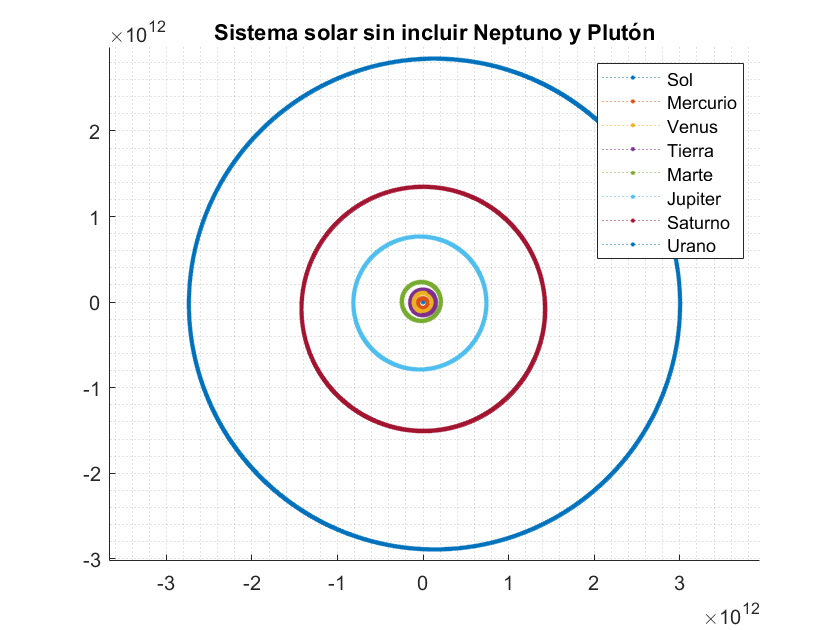

figure
hold on
for i=1:8
    plot3(y1840(3*i-2,:),y1840(3*i-1,:),y1840(3*i,:),':.')
end
hold off
grid minor
title('Sistema solar sin incluir Neptuno y Plutón')
legend('Sol','Mercurio','Venus','Tierra','Marte','Jupiter','Saturno','Urano')
axis equal

#### Incluyendo los efectos de Neptuno y Plutón

y0=[r0;v0];     %vector de posiciones y velocidades iniciales

[t,y2020]=odeRK4(fhandle,y0,t0,tf,h);

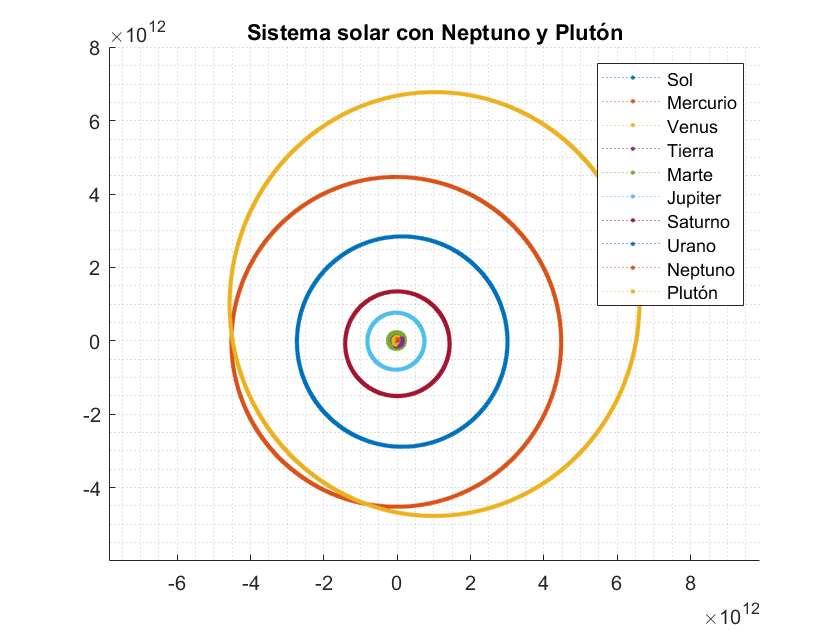

figure
hold on
for i=1:10
    plot3(y2020(3*i-2,:),y2020(3*i-1,:),y2020(3*i,:),':.')
end
hold off
grid minor
title('Sistema solar con Neptuno y Plutón')
legend('Sol','Mercurio','Venus','Tierra','Marte','Jupiter','Saturno','Urano','Neptuno','Plutón')
axis equal

#### Análisis de estabilidad de los resultados

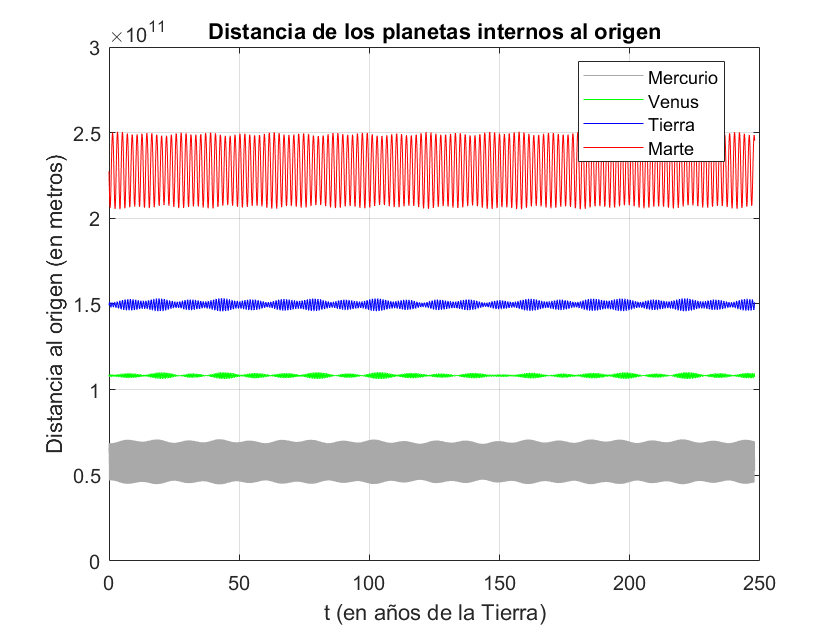

rInner=y2020(4:15,:);
dMerc=sqrt(rInner(1,:).^2+rInner(2,:).^2+rInner(3,:).^2);
dVenu=sqrt(rInner(4,:).^2+rInner(5,:).^2+rInner(6,:).^2);
dEart=sqrt(rInner(7,:).^2+rInner(8,:).^2+rInner(9,:).^2);
dMars=sqrt(rInner(10,:).^2+rInner(11,:).^2+rInner(12,:).^2);
tYears=t/(60*60*24*365.25);

plot(tYears,dMerc,'color','#A9A9A9')
hold on
plot(tYears,dVenu,'g')
plot(tYears,dEart,'b')
plot(tYears,dMars,'r')
hold off
grid on
xlabel('t (en años de la Tierra)')
ylabel('Distancia al origen (en metros)')
title('Distancia de los planetas internos al origen')
legend('Mercurio','Venus','Tierra','Marte','location',"best")

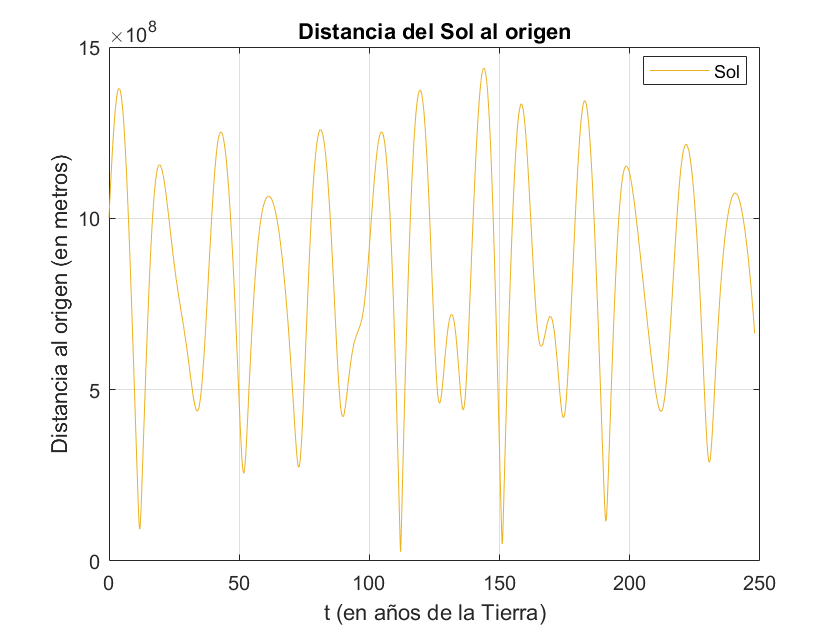


rSun=y2020(1:3,:);
dSun=sqrt(rSun(1,:).^2+rSun(2,:).^2+rSun(3,:).^2);
plot(tYears,dSun,"Color",'#EDB120')
grid on
xlabel('t (en años de la Tierra)')
ylabel('Distancia al origen (en metros)')
title('Distancia del Sol al origen')
legend('Sol','location',"best")

## Comparación animada de resultados sobre la órbita de Urano

rUrano1840=y1840(22:24,:);
rUrano2020=y2020(22:24,:);
rNeptuno=y2020(25:27,:);

rdUrano=rUrano2020-rUrano1840;
dUrano=sqrt(rdUrano(1,:).^2+rdUrano(2,:).^2+rdUrano(3,:).^2);

%generacion de animacion del movimiento
figure

n=fix(length(t)/(12*180));

Unrecognized function or variable 't'.

F(n) = struct('cdata',[],'colormap',[]);
for i=1:n
    %se muestra la posicion y trail de Urano y Neptuno
    subplot(2,1,1)
    plot(rUrano1840(1,1:12*180:12*180*i),rUrano1840(2,1:12*180:12*180*i),':r')
    hold on
    plot(rUrano2020(1,1:12*180:12*180*i),rUrano2020(2,1:12*180:12*180*i),':b')
    plot(rNeptuno(1,1:12*180:12*180*i),rNeptuno(2,1:12*180:12*180*i),':m')
    
    plot(rUrano1840(1,12*180*i),rUrano1840(2,12*180*i),'or')
    plot(rUrano2020(1,12*180*i),rUrano2020(2,12*180*i),'ob')
    plot(rNeptuno(1,12*180*i),rNeptuno(2,12*180*i),'om')
    
    axis([-5e12 5e12 -5e12 5e12])
    grid minor
    title('Órbitas de Urano y Neptuno')
    xlabel('rX (metros)')
    ylabel('rY (metros)')
    legend('Urano 1840','Urano 2020','Neptuno','location',"best")
    hold off
    
    %diferencia en las posiciones de Urano
    subplot(2,1,2)
    plot(tYears(1,1:12*180:12*180*i),dUrano(1,1:12*180:12*180*i),'xr')
    grid on
    title('Diferencia entre las órbitas de Urano')
    xlabel('t (en años de la Tierra)')
    ylabel('Distancia (en metros)')
    axis([0 250 0 8e9])
    F(i)=getframe(gcf);
end

fps=n/10;
%para ver la animacion se debe correr el siguiente comando en la CmdWindow
%movie(F,2,fps)

## Análisis de resultados

    En la gráfica de la sección de comparación de resultados se puede ver que la distancia entre las posiciones de Urano (el error entre la realidad y lo supuesto para 1840) presenta un crecimiento con el paso del tiempo. Debido a que se tomaron las posiciones reales de los cuerpos del sistema solar como condición inicial del sistema, se puede suponer que el modelo que no incluye a Neptuno debería tener condiciones iniciales distintas y tiende a un estado estable correspondiente a un sistema solar que nunca incluyó a planetas más lejanos que Urano. Si esta simulación se corriera por más tiempo se podría esperar diferencias mayores en la órbita de Urano. Por otro lado, se observa también un incremento considerable en el error cuando Urano coincide con Neptuno, es decir, la cercanía de Neptuno genera anomalías en la órbita de Urano. Fuerno estas anomalías las que [John Couch Adams](https://en.wikipedia.org/wiki/John_Couch_Adams) y [Urbain Le Verrier](https://en.wikipedia.org/wiki/Urbain_Le_Verrier) investigaron en la década de 1840 y los llevó al descubrimiento teórico de Neptuno. En la gráfica llamada "Diferencia entre las órbitas de Urano" se puede observar que la máxima diferencia de metros en la órbita se encuentra en el intervalo 150-200 años, ese es el intervalo que contiene el periodo de revoluciones alrededor del sol de Neptuno ([164.81](https://www.enchantedlearning.com/subjects/astronomy/planets/) años terrestres)

## Conclusiones

La implementación de este proyecto en MATLAB no fue algo trivial, lo que  nos abrió los ojos pues nos dimos cuenta que aunque puede parecernos que tarda mucho en correr (aproximadamente 5 minutos), eso no es nada en comparación con el esfuerzo que encontrar un planeta con lapiz y papel debe de haber sido.  Además, para poder realizar satisfactoriamente el proyecto tuvimos que hacer una investigación importante sobre el sistema solar y aprendimos varias cosas:

- No importa que las órbitas de Plutón y Neptuno se crucen pues en su periodo de revolución que tiene cada uno es distinto. 

- Neptuno no puede verse a simple vista, es necesario utilizar un telescopio.

- La medida para ver la distancia entre los planetas y el sol es AU (Astronomical Units) y 1AU¡1.496e+8km.

- Existe una teoría que dice que Galileo encontró Neptuno y lo consideraba una [estrella.](https://www.space.com/6941-theory-galileo-discovered-neptune.html)

El descubrimiento de Neptuno no solo resolvió el misterio de las anomaías, sino que muchas de las cosas que se creían ciertas en ese momento fueron refutadas. Un claro ejemplo de esto es la Ley de Titius-Bode que se creía la fórmula para encontrar la distancia entre los planetas.

La Ley de Titius-Bode dice que: $a=0.4+0.3*2^m$ (nota: el primer valor es 0.4, a partir del segundo se cuenta m como uno).

disAU=[0.39; 0.72;1.00;1.52;5.20;9.53;19.18;30.06];
names={'Mercurio';'Venus'; 'Tierra'; 'Marte'; 'Jupiter'; 'Saturno'; 'Urano'; 'Neptuno'};

pos=zeros(8,1);
pos(2)=.3;
for i=3:1:8
    pos(i)=pos(i-1)*2;
end
pos=(pos+.4);

plot(pos, 'o')
hold on
plot(disAU,'*')

set(gca,'xtick',(1:8),'xticklabel',names)
legend('Aproximados por Ley de Bode', 'Valores reales','Location','northwest')
title('Distancia de los planetas al sol en AU')
xlabel('Planetas')
ylabel('AU')
grid on
hold off
err=pos-disAU;
plot(abs(err));
xlabel('Planetas')
ylabel('AU')
set(gca,'xtick',(1:8),'xticklabel',names)
title("Diferencia entre el valor aproximado y el real")
grid on

Cómo se puede ver en la gráfica que muestra la diferencia de valores calculados con la ley de Titius-Bode con la distancia real que hay entre los planetas y el sol, tanto Urano como Neptuno tienen una distancia mayor a 8AU. Esta diferencia fue suficiente para refutar la ley, ahora se considera una curiosidad que la ley empírica coincida con los primeros planetas.

## Funciones utilizadas

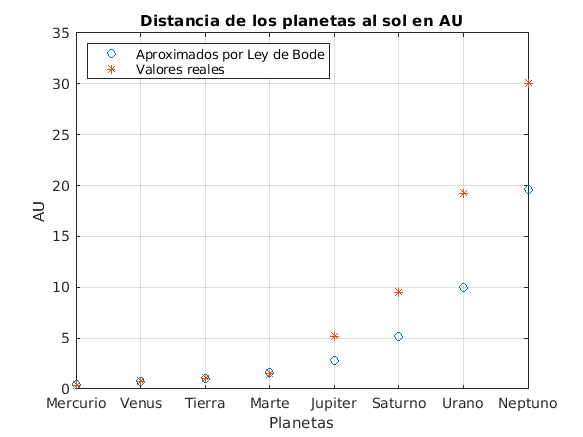

function dy = f(~,y)

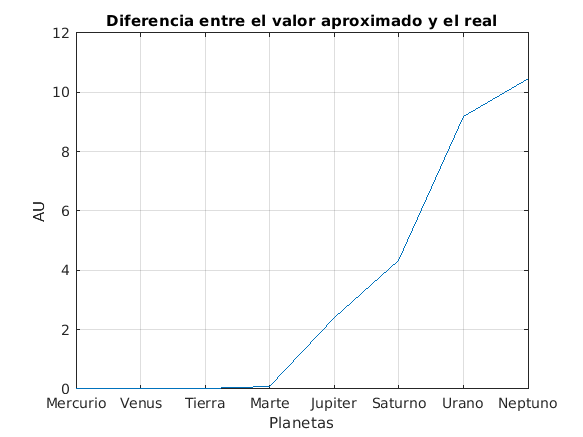

    global G m;
    n=length(y)/2;
    r = y(1:n);    %vector de posicion
    v = y(n+1:end);   %vector de velocidad
    
    c=length(r)/3;
    rji=zeros(3,c,c);

    for i=1:c
        rf=r(3*i-2:3*i);
        for j=1:c
            rji(:,j,i)=r(3*j-2:3*j)-rf;
        end
    end
    
    r3=sqrt(rji(1,:,:).^2+rji(2,:,:).^2+rji(3,:,:).^2).^3;
    
    a=zeros(c*3,1);
    for i=1:c
        a(3*i-2:3*i)=rji(:,[1:i-1 i+1:c],i)*(m([1:i-1 i+1:c])./r3(1,[1:i-1 i+1:c],i)');
    end
    a=G*a;
    
    dy=[v;a];
end

function [t,y] = odeRK4(f,y0,t0,tf,h)
    t=t0:h:tf;
    n=length(t);
    y=zeros(length(y0),n);
    y(:,1)=y0;
    for i=1:n-1
        k1=f(t(i),y(:,i));
        k2=f(t(i)+0.5*h,y(:,i)+0.5*k1*h);
        k3=f(t(i)+0.5*h,y(:,i)+0.5*k2*h);
        k4=f(t(i)+h,y(:,i)+k3*h);
        phi=(k1+2*k2+2*k3+k4)/6;
        y(:,i+1)=y(:,i)+phi*h;
    end
end

function [t,y] = odeRKF45(f,y0,t0,tf,h0,rTol,maxI)
    y(:,1)=y0;
    t(1)=t0;
    h=h0;
    i=1;
    while t(i)<tf
        j=0;
        cond=true;
        while cond
            s1=f(t(i),y(:,i));
            s2=f(t(i)+(1/4)*h,y(:,i)+(1/4)*s1*h);
            s3=f(t(i)+(3/8)*h,y(:,i)+(3/32)*s1*h+(9/32)*s2*h);
            s4=f(t(i)+(12/13)*h,y(:,i)+(1932/2197)*s1*h-(7200/2197)*s2*h+(7296/2197)*s3*h);
            s5=f(t(i)+h,y(:,i)+(439/216)*s1*h-8*s2*h+(3680/513)*s3*h-(845/4104)*s4*h);
            s6=f(t(i)+(1/2)*h,y(:,i)-(8/27)*s1*h+2*s2*h-(3544/2565)*s3*h+(1859/4104)*s4*h-(11/40)*s5*h);
            w4=y(:,i)+h*(s1*25/216+s3*1408/2565+s4*2197/4104-s5/5);
            w5=y(:,i)+h*(s1*16/135+s3*6656/12825+s4*28561/56430-s5*9/50+s6*2/55);
            j=j+1;
            e=norm((w5-w4)/w5,inf);
            cond= e>rTol && j<maxI;
            if cond
                h=h/2;
            end
        end
        y(:,i+1)=w4;
        t(i+1)=t(i)+h;
        if e<rTol/2
            h=2*h;
        end
        i=i+1;
    end
end

## Referencias

[1] Bode's law | astronomy. (2020). Retrieved 23 May 2020, from [https://www.britannica.com/science/Bodes-law](https://www.britannica.com/science/Bodes-law)

[2] (n.d.). Retrieved from https://www.enchantedlearning.com/subjects/astronomy/planets/ 

[3] HORIZONS User Manual. (n.d.). Retrieved from https://ssd.jpl.nasa.gov/?horizons_doc 

[4] Ordinary differential equations: solar system¶. (n.d.). Retrieved from  https://numerical-analysis.readthedocs.io/en/latest/ODE/ODE_solar_system.html 

[5] Solar System Dynamics. (n.d.). Retrieved from  https://books.google.com.mx/books?hl=en&lr=&id=aU6vcy5L8GAC&oi=fnd&pg=PR11&dq=solar+system+differential+equations&ots=CBgU-z4vOm&sig=91NdzTo7Wr-Ge68U7cYmOE3DLxY&redir_esc=y#v=onepage&q=solar system differential equations&f=false 